# Problema1

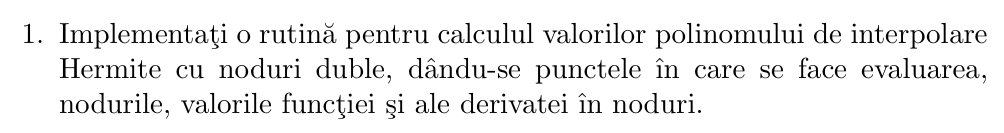

Interpolarea Hermite este o metoda de a aproxima o functie nu doar folosind valorile functiei in anumite puncte (asa cum face interpolarea Lagrange sau Newton), ci si valorile derivatei functiei in cele puncte

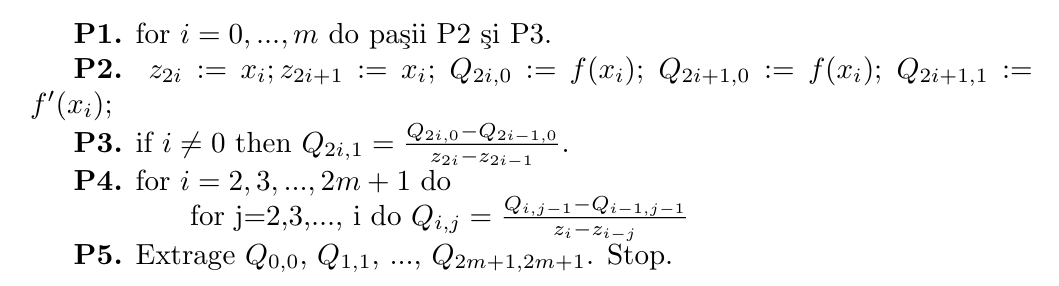

function [p_val, coef, z] = interpolareHermite(x, f, df, x_eval)
% INTERPOLAREHERMITE - Interpolare Hermite cu noduri duble (forma Newton)
%
% INPUT:
%   x       - vector cu nodurile xi (lungime n)
%   f       - valorile functiei f(xi)
%   df      - valorile derivatei f'(xi)
%   x_eval  - punctele in care se evalueaza polinomul
%
% OUTPUT:
%   p_val   - valorile interpolate in punctele x_eval
%   coef    - coeficientii Newton ai polinomului Hermite
%   z       - vectorul de noduri extinse (cu dubluri)

    n = length(x);        % numarul de noduri initiale
    m = 2 * n;            % numarul de linii in tabela (fiecare nod apare de 2 ori)
    
    z = zeros(1, m);      % vectorul de noduri extinse: z_0, z_1, ..., z_{2n-1}
    Q = zeros(m, m);      % tabela Hermite de diferente divizate

    % P1, P2 
    for i = 1:n
        z(2*i - 1) = x(i);               
        z(2*i)     = x(i);              
        
        Q(2*i - 1, 1) = f(i);            
        Q(2*i,     1) = f(i);          
        
        Q(2*i,     2) = df(i);           

        % P3 - Daca nu suntem pe primul nod, calculam Q_{2i,1} 
        if i ~= 1
            Q(2*i - 1, 2) = (Q(2*i - 1, 1) - Q(2*i - 2, 1)) / ...
                           (z(2*i - 1) - z(2*i - 2));
        end
    end

    % P4 - Completam tabela Hermite (diferente divizate de ordin superior) 
    for i = 3:m
        for j = 3:i
            Q(i,j) = (Q(i,j-1) - Q(i-1,j-1)) / (z(i) - z(i-j+1));
        end
    end

    % P5 - Extragem coeficientii de pe diagonala
    coef = diag(Q);  % coeficientii din forma Newton

    % Evaluare polinom Hermite in punctele x_eval 
    p_val = zeros(size(x_eval));  % vector rezultat

    for k = 1:length(x_eval)
        val = coef(1);             % pornim cu primul coeficient
        produs = 1;

        for j = 2:m
            produs = produs * (x_eval(k) - z(j-1));
            val = val + coef(j) * produs;
        end

        p_val(k) = val;
    end
end


function este_derivabila = verificaDerivabilitateGlobala(f, x_noduri, tol)
% VERIFICADERIVABILITATEGLOBALA - Verifica daca functia f este derivabila
% in toate punctele din vectorul de noduri x_noduri.
%
% Aceasta functie compara derivata stanga si derivata dreapta numerica
% in fiecare punct dat. Daca toate diferentele sunt mai mici decat
% toleranta tol, functia se considera derivabila peste toate nodurile.
%
% INPUT:
%   f            - functie anonima (de tipul f = @(x) ...)
%   x_noduri     - vector cu punctele unde verificam derivabilitatea
%   tol          - toleranta (ex: 1e-4) sub care consideram ca derivata exista
%
% OUTPUT:
%   este_derivabila - true daca f este derivabila in toate punctele din x_noduri

    h = 1e-5;                     % pas mic pentru aproximare numerica
    este_derivabila = true;       % presupunem ca functia e derivabila

    % Parcurgem fiecare punct
    for i = 1:length(x_noduri)
        x0 = x_noduri(i);        % punctul curent

        % Derivata stanga si dreapta (finite differences)
        d_st = (f(x0) - f(x0 - h)) / h;
        d_dr = (f(x0 + h) - f(x0)) / h;

        % Verificam daca diferentele sunt prea mari
        if abs(d_st - d_dr) >= tol
            fprintf('[!] Functia NU este derivabila in x = %.5f\n', x0);
            este_derivabila = false;
            return;             % iesim imediat daca gasim o neregularitate
        end
    end
end


function df_val = calculeazaDerivataSigura(f, x_noduri)
% CALCULEAZADERIVATASIGURA - Calculeaza derivata functiei f in nodurile date
% folosind formula diferentei centrate, fara verificare prealabila.
%
% Aceasta functie presupune ca functia este deja derivabila.
% Derivarea se face cu o aproximare centrata de ordin 2.
%
% INPUT:
%   f         - functie anonima (ex: @(x) sin(x))
%   x_noduri  - vector cu punctele in care se calculeaza derivata
%
% OUTPUT:
%   df_val    - vector cu valorile aproximative ale derivatelor in punctele respective

    h = 1e-5;  % pas mic pentru derivare centrata

    % Aplicam formula derivatei centrate: f'(x) ≈ [f(x+h) - f(x-h)] / (2h)
    df_val = (f(x_noduri + h) - f(x_noduri - h)) ./ (2*h);
end


f_sym = @(x) x.^3 - 2*x.^2 + x + 1;         % functia f(x)
x = [1.3, 1.6, 1.9];                        % nodurile

if verificaDerivabilitateGlobala(f_sym, x, 1e-4)
    fprintf('Putem folosi interpolarea hermite');
    df = calculeazaDerivataSigura(f_sym, x);
else
    error('Interpolare Hermite imposibila: functia nu este derivabila in toate nodurile.');
end

Putem folosi interpolarea hermite


f = f_sym(x);
x_eval = 1.5;

[p_val, coef, z] = interpolareHermite(x, f, df, x_eval);

fprintf('Interpolare Hermite la x=%.2f: %.10f\n', x_eval, p_val);

Interpolare Hermite la x=1.50: 1.3750000000


fprintf('Valoare exacta f(x):           %.10f\n', exp(0.25));

Valoare exacta f(x):           1.2840254167


fprintf('Eroare absoluta:               %.10e\n', abs(p_val - exp(0.25)));

Eroare absoluta:               9.0974583302e-02


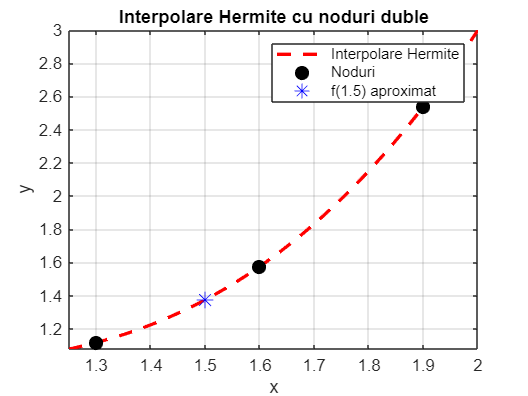



xx = linspace(1.25, 2.0, 400);               
yy_hermite = interpolareHermite(x, f, df, xx);  

figure;
plot(xx, yy_hermite, 'r--', 'LineWidth', 2); hold on;
plot(x, f, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
plot(x_eval, p_val, 'b*', 'MarkerSize', 10);                   
legend('Interpolare Hermite', 'Noduri', 'f(1.5) aproximat');
xlabel('x'); ylabel('y');
title('Interpolare Hermite cu noduri duble');
grid on; axis tight;